Find the frequency components of a signal buried in noise and find the amplitudes of the peak frequencies by using Fourier transform.

Specify the parameters of a signal with a sampling frequency of 1 kHz and a signal duration of 1.5 seconds.

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 2000;             % Length of signal
t = (0:L-1)*T;        % Time vector

Form a signal containing a DC offset of amplitude 0.8, a 50 Hz sinusoid of amplitude 0.7, and a 120 Hz sinusoid of amplitude 1.

S = 0.8 + 0.7*sin(2*pi*50*t);% + sin(2*pi*120*t);

Corrupt the signal with zero-mean random noise with a variance of 4.

X = S ; %+ 2*randn(size(t));

Plot the noisy signal in the time domain. The frequency components are not visually apparent in the plot.

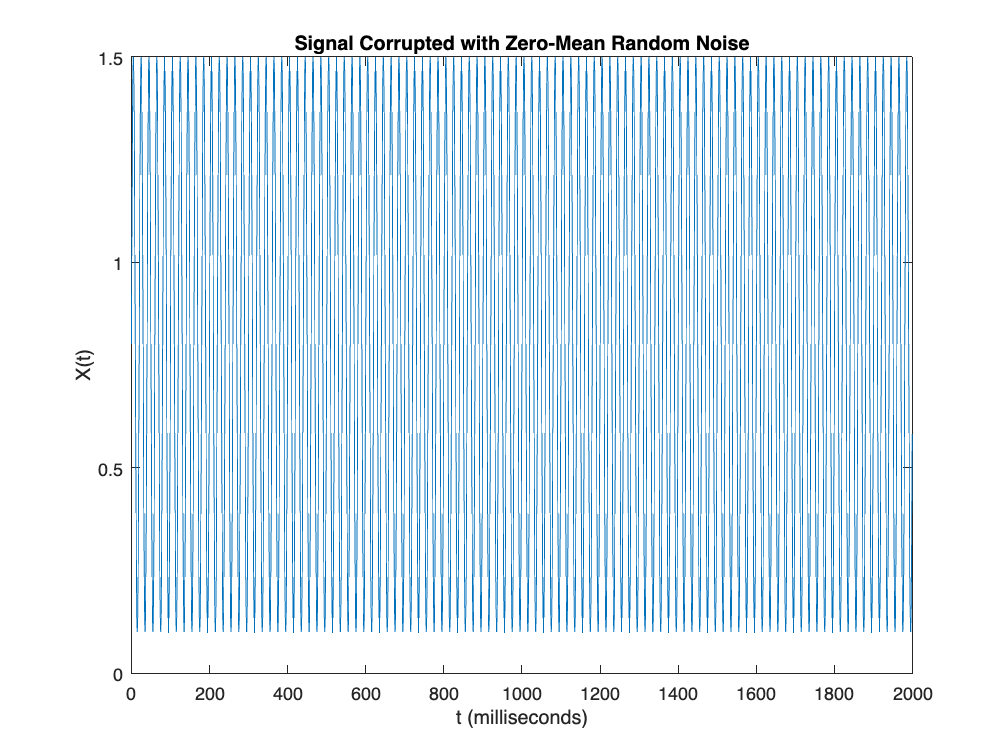

plot(1000*t,X)
title("Signal Corrupted with Zero-Mean Random Noise")
xlabel("t (milliseconds)")
ylabel("X(t)")

Compute the Fourier transform of the signal. 

%Y = fft(X);
Y = fft(X(1:length(X)/2));

Because Fourier transforms involve complex numbers, plot the complex magnitude of the `fft` spectrum.

plot(Fs/L*(0:L-1),abs(Y),"LineWidth",3)

Error using plot
Vectors must be the same length.

%plot(Fs/L*(0:length(Y)-1),abs(Y),"LineWidth",3);
title("Complex Magnitude of fft Spectrum")
xlabel("f (Hz)")
ylabel("|fft(X)|")

xlim([0 1000])
ylim([12 1200])

The plot shows five frequency peaks including the peak at 0 Hz for the DC offset. In this example, the signal is expected to have three frequency peaks at 0 Hz, 50 Hz, and 120 Hz. Here, the second half of the plot is the mirror reflection of the first half without including the peak at 0 Hz. The reason is that the discrete Fourier transform of a time-domain signal has a periodic nature, where the first half of its spectrum is in positive frequencies and the second half is in negative frequencies, with the first element reserved for the zero frequency.

For real signals, the `fft` spectrum is a two-sided spectrum, where the spectrum in the positive frequencies is the complex conjugate of the spectrum in the negative frequencies. To show the `fft` spectrum in the positive and negative frequencies, you can use `fftshift`. For an even length of `L`, the frequency domain starts from the negative of the Nyquist frequency `-Fs/2` up to `Fs/2-Fs/L` with a spacing or frequency resolution of `Fs/L`.

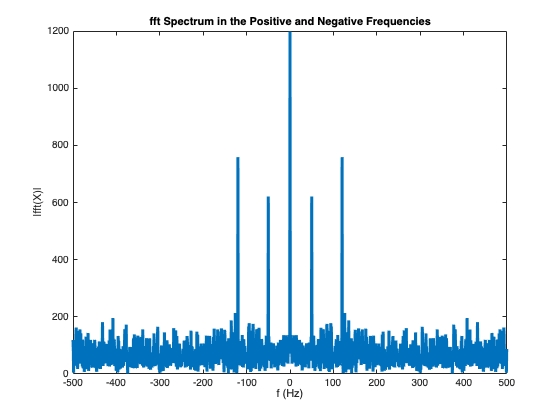

plot(Fs/L*(-L/2:L/2-1),abs(fftshift(Y)),"LineWidth",3)
title("fft Spectrum in the Positive and Negative Frequencies")
xlabel("f (Hz)")
ylabel("|fft(X)|")

To find the amplitudes of the three frequency peaks, convert the `fft` spectrum in `Y` to the single-sided amplitude spectrum. Because the `fft` function includes a scaling factor `L` between the original and the transformed signals, rescale `Y` by dividing by `L`. Take the complex magnitude of the `fft` spectrum. The two-sided amplitude spectrum `P2`, where the spectrum in the positive frequencies is the complex conjugate of the spectrum in the negative frequencies, has half the peak amplitudes of the time-domain signal. To convert to the single-sided spectrum, take the first half of the two-sided spectrum `P2`. Multiply the spectrum in the positive frequencies by 2. You do not need to multiply `P1(1)` and `P1(end)` by 2 because these amplitudes correspond to the zero and Nyquist frequencies, respectively, and they do not have the complex conjugate pairs in the negative frequencies.

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

Define the frequency domain `f` for the single-sided spectrum. Plot the single-sided amplitude spectrum `P1`. As expected, the amplitudes are close to 0.8, 0.7, and 1, but they are not exact because of the added noise. In most cases, longer signals produce better frequency approximations.

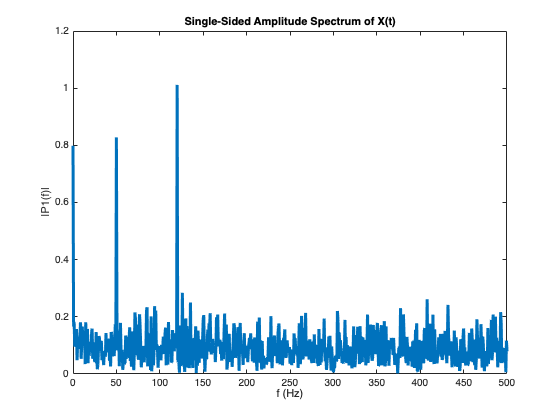

f = Fs/L*(0:(L/2));
plot(f,P1,"LineWidth",3) 
title("Single-Sided Amplitude Spectrum of X(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

Now, take the Fourier transform of the original, uncorrupted signal and retrieve the exact amplitudes at 0.8, 0.7, and 1.0.

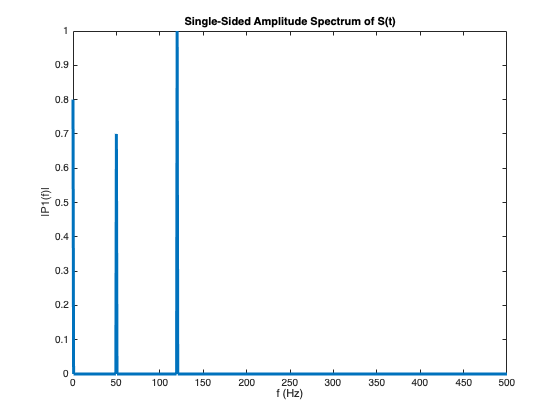

Y = fft(S);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

plot(f,P1,"LineWidth",3) 
title("Single-Sided Amplitude Spectrum of S(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

*Copyright 2012 The MathWorks, Inc.*